## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
addpath(['~/Documents/Courses/'...
    'ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/matlab/functions']);

### Load soundfile

clear all;
addpath(['~/Documents/Courses/ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/snd']);

[X, Fs] = audioread('pori.wav');

# Collect multiple uniform segments into matrix

starttime = 0.1;    % start time (seconds)
endtime = 2.2;      % don't get any window past this point
wintime = 2048/Fs;  % window duration (seconds) - paper uses 2048 samples
% wintime = 0.04;   % window duration (seconds) - paper uses 2048 samples
hoptime = wintime;

rangetime = endtime-starttime;
nWin = floor(rangetime/hoptime);
nWinSamps = floor(wintime * Fs);

segments = zeros(nWinSamps, nWin);

for i = 1:nWin
    st = starttime + (hoptime * (i-1));
    st = floor(st*Fs);
    segments(:, i) = getSamples(X, st, nWinSamps);
%     subplot(nWin,1,i);
%     plot(segments(:,i)); ylim([-1 1] *0.03); hold on;
end
hold off;

clear X starttime endtime wintime hoptime rangetime nWin nWinSamps st i

# [Alt] Manual signal sementation

n = 100:150:2000;             % time points which to measure [ms]
M = 100 * ones(length(n), 1); % durations of segments to measure [ms]

% convert miliseconds to samples
n = round(n ./1000 .*Fs); 
M = round(M ./1000 .*Fs);
segments = {};
for i = 1:length(n)
    st = n(i);
    len = M(i);
    segments{i} = X(st:st+len-1);
end
clear i M n

## LPC spectral estimate on matrix

#### Run above segmentation to populate 'seg' variable.

lpcOrder = 6;        % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(segments, lpcOrder, frq_resolution, Fs);

### [Alt] LPC spectral estimate on cell array

lpcOrder = 6;            % LPC Allpole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

nSig     = length(seg);  % number of signals to analyze
specEnv  = zeros(frq_resolution, nSig); % a matrix to hold all the segments' spectral envs
specNorm = zeros(frq_resolution, nSig);

for i = 1:nSig
    [mags mags_norm freqs coeffs] = ...
        lpcData(seg{i}, lpcOrder, frq_resolution, Fs);
    specEnv(:, i)  = mags;
    specNorm(:, i) = mags_norm;
end

mags = specEnv;
mags_norm = specNorm;

clear nSig specEnv specNorm

#### Manupulate magnitudes for plotting

% offset normalized magnitudes by segment's RMS
segrms = mag2db(rms(segments)); % get rms of each segment
segrms = segrms - max(segrms);  % shift rms's max to 0

% shift each segment response by it's rms
mags_rms_shift = mags_norm + segrms;  % normalized mags
% mags_rmsshift = mags + segrms;      % lpc mags

### Plot spectral estimate magnitudes

plot_rolloff_pnts = true; % plot rolloff point markers?
nchan = size(mags, 2);    % number of channels available
plot_idx = (1:nchan);   % which channels to plot
nplot = length(plot_idx); % number of channels being plotted

% select which data to plot
% data = mags_rms_shift(:, plot_idx);
data = mags_norm(:,plot_idx);
% data = mags(:,plot_idx);

plt = semilogx(freqs, data, "LineWidth", 1.5);

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nplot);

% plot cutoff markers
if ~plot_rolloff_pnts
    legend("Location", "SouthWest");
    legend('Position',[0.18 0.2 0.15 0.2]);
else
    hold on;
    rolloff  = -20;  % rolloff to detect, in dB
    min_freq = 750;  % don't search below this frequency
    
    [idxs, rollofffreqs, rolloffvals] = ...
        rolloffIdx(mags_norm(:,plot_idx), rolloff, min_freq, Fs);
    
    % keep track of the plots for legend management
    plts = {}; 
    plts{1} = plt; % add the spectral lines plot (from prev block)
    
    for i = 1:length(idxs)
        plt = semilogx( ...
            freqs(idxs(i)), data(idxs(i), i), ...
            "LineStyle", "none", "Marker", "*");
        plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
        plts{i+1} = plt; % +1: plts{1} is the array of line plots 
    end
    
    % colors
    colororder([rgb; rgb]); % repeated so line and marker colors match
    
    legend([ ...
        plts{1}(1) ... % first of the line plots
        plts{2} ...    % first of the rolloff markers
        ],[ ...
            "segment spectrum" ...
            string(rolloff) + " rolloff point" ...
        ]);
    legend("Location", "West");
    % legend('Position',[0.18 0.2 0.15 0.2]);
    hold off;
end

colororder(rgb);
axis tight;    
xlim([80 20000]);
% ylim([-100 0])
xticks(125*2.^(0:7)) % octaves: 125 > 16000

clear nplot plot_idx

# Calculate first and last -20dB rolloff frequencies, and rms

nOutSegements = 24;
rolloff = -20; % rolloff to detect, in dB
min_freq = 750;

[idxs, rollofffreqs, rolloffvals] = ...
        rolloffIdx(mags_norm(:,[1 end]), rolloff, min_freq, Fs);
    
firstrms = rms(segments(:, 1));
lastrms = rms(segments(:, end));

% Evenly distribute frequency cutoff of each segment 
% bettween first and last segments' -20dB rolloff frequency
% rollofffreqs = linspace(f(1), f(end), nSig); % linear frequency spacing
 % logarithmic frequency spacing
rollofffreqs = exp(linspace( ...
    log(rollofffreqs(1)), log(rollofffreqs(end)), nOutSegements ...
    ));
rolloffrms = linspace(firstrms, lastrms, nOutSegements);

## Assign segment boundary to each frequency division (retry)

starttime = 0.1;    % start time (seconds)
winsize = 2048;  % analysis window size
hopsize = 500;   % analysis window hop

start = floor(starttime * Fs);
nwin = floor(((length(X) - start) - (winsize-hopsize)) / (hopsize+1));
segments = zeros(winsize, nwin);

% collect the "sliding window" of samples
winStSamps = zeros(nwin, 1);
for i = 1:nwin
    st = start + (hopsize * (i-1));
    winStSamps(i) = st;
    segments(:, i) = getSamples(X, st, winsize);
end


## LPC spectral estimate on matrix

lpcOrder = 10;           % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(segments, lpcOrder, frq_resolution, Fs);

[rollidxs, rollfreqs, rollvals] = rolloffIdx(mags_norm, -20, 1500, Fs)

### Plot frequency rolloff by window

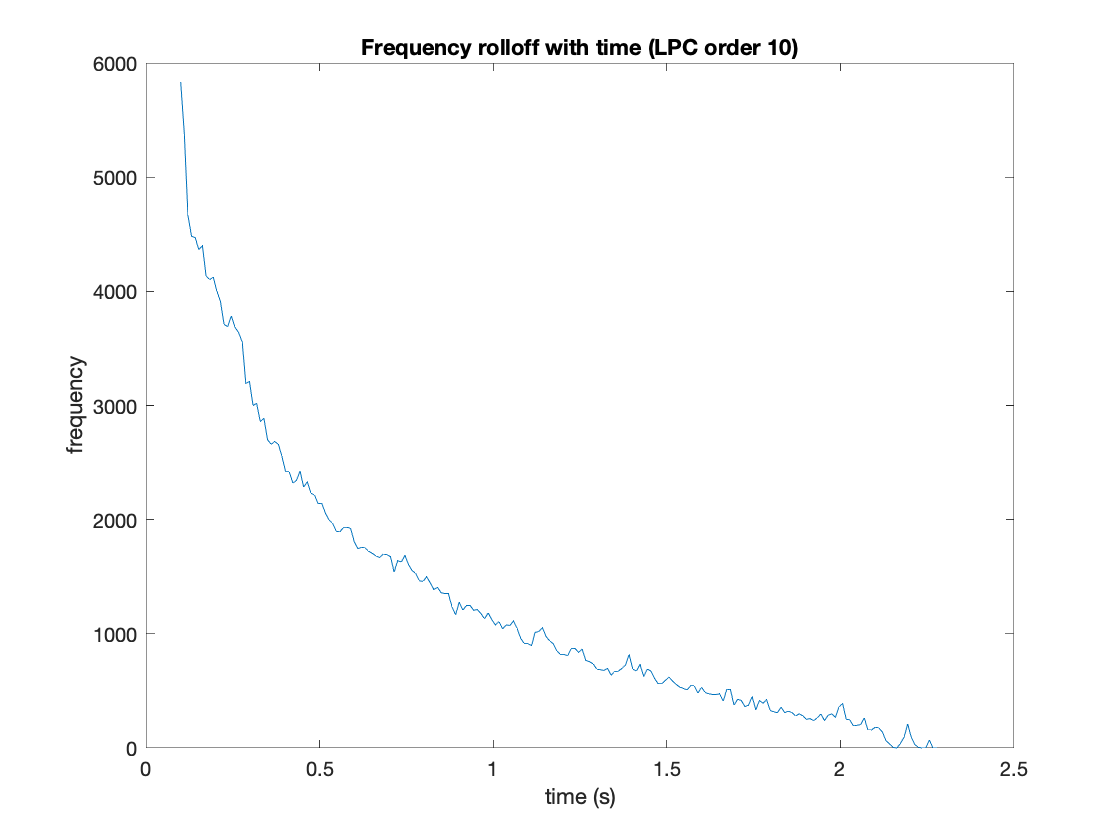

plot(winStSamps / Fs, rollfreqs);
xlabel('time (s)')
ylabel('frequency')
title(strcat("Frequency rolloff with time (LPC order ", string(lpcOrder), ")"))

### Find which analysis windows mark segment boundaries

frqHigh = rollfreqs(1);
frqLow  = 260; % found through inspection
segthresh = 0.05; % percentage of frqHigh to advance between segments
freqstep = frqHigh * segthresh;

segStartIdxs = [winStSamps(1)];
cnt = 1; % analysis window counter
nextBoundaryFrq = frqHigh - freqstep

nextBoundaryFrq = 5.5386e+03


while (nextBoundaryFrq >= frqLow) && (cnt <= length(rollidxs))
    thisfrq = rollfreqs(cnt)
    if (thisfrq < nextBoundaryFrq)
        % add this window's start frame to the segment boundary list
        segStartIdxs = [segStartIdxs winStSamps(cnt)];
        
        nextBoundaryFrq = nextBoundaryFrq - freqstep
    end
    cnt = cnt+1;
end

thisfrq = 5.8301e+03

thisfrq = 5.3789e+03

nextBoundaryFrq = 5.2471e+03

thisfrq = 4.6641e+03

nextBoundaryFrq = 4.9556e+03

thisfrq = 4.4824e+03

nextBoundaryFrq = 4.6641e+03

thisfrq = 4.4707e+03

nextBoundaryFrq = 4.3726e+03

thisfrq = 4.3652e+03

nextBoundaryFrq = 4.0811e+03

thisfrq = 4.4004e+03

thisfrq = 4.1367e+03

thisfrq = 4.1016e+03

thisfrq = 4125

thisfrq = 4.0020e+03

nextBoundaryFrq = 3.7896e+03

thisfrq = 3.9082e+03

thisfrq = 3.7090e+03

nextBoundaryFrq = 3.4980e+03

thisfrq = 3.6914e+03

thisfrq = 3.7852e+03

thisfrq = 3.6855e+03

thisfrq = 3.6387e+03

thisfrq = 3.5566e+03

thisfrq = 3.1934e+03

nextBoundaryFrq = 3.2065e+03

thisfrq = 3.2109e+03

thisfrq = 3000

nextBoundaryFrq = 2.9150e+03

thisfrq = 3.0176e+03

thisfrq = 2.8594e+03

nextBoundaryFrq = 2.6235e+03

thisfrq = 2.8887e+03

thisfrq = 2.7012e+03

thisfrq = 2.6602e+03

thisfrq = 2.6836e+03

thisfrq = 2.6602e+03

thisfrq = 2.5547e+03

nextBoundaryFrq = 2.3320e+03

thisfrq = 2.4199e+03

thisfrq = 2.4199e+03

thisfrq = 2.3203e+03

nextBoundaryFrq = 2.0405e+03

thisfrq = 2.3438e+03

thisfrq = 2.4258e+03

thisfrq = 2.2852e+03

thisfrq = 2.3320e+03

thisfrq = 2.2324e+03

thisfrq = 2.2148e+03

thisfrq = 2.1387e+03

thisfrq = 2.1445e+03

thisfrq = 2.0566e+03

thisfrq = 1.9980e+03

nextBoundaryFrq = 1.7490e+03

thisfrq = 1.9688e+03

thisfrq = 1.8984e+03

thisfrq = 1.8926e+03

thisfrq = 1.9336e+03

thisfrq = 1.9336e+03

thisfrq = 1.9219e+03

thisfrq = 1.8047e+03

thisfrq = 1.7461e+03

nextBoundaryFrq = 1.4575e+03

thisfrq = 1.7578e+03

thisfrq = 1.7520e+03

thisfrq = 1.7227e+03

thisfrq = 1.7051e+03

thisfrq = 1.6816e+03

thisfrq = 1.6699e+03

thisfrq = 1.6992e+03

thisfrq = 1.6934e+03

thisfrq = 1.6758e+03

thisfrq = 1.5410e+03

thisfrq = 1.6406e+03

thisfrq = 1.6289e+03

thisfrq = 1.6875e+03

thisfrq = 1.6055e+03

thisfrq = 1.5527e+03

thisfrq = 1.5293e+03

thisfrq = 1.4648e+03

thisfrq = 1.4590e+03

thisfrq = 1500

thisfrq = 1.4473e+03

nextBoundaryFrq = 1.1660e+03

thisfrq = 1.3887e+03

thisfrq = 1.4063e+03

thisfrq = 1.3594e+03

thisfrq = 1.3535e+03

thisfrq = 1.3535e+03

thisfrq = 1.2363e+03

thisfrq = 1.1660e+03

thisfrq = 1.2773e+03

thisfrq = 1.2070e+03

thisfrq = 1.2480e+03

thisfrq = 1.2480e+03

thisfrq = 1.2070e+03

thisfrq = 1.2129e+03

thisfrq = 1.1777e+03

thisfrq = 1.1309e+03

nextBoundaryFrq = 874.5117

thisfrq = 1.1836e+03

thisfrq = 1125

thisfrq = 1.0781e+03

thisfrq = 1.1074e+03

thisfrq = 1.0430e+03

thisfrq = 1.0781e+03

thisfrq = 1.0723e+03

thisfrq = 1.1133e+03

thisfrq = 1.0488e+03

thisfrq = 960.9375

thisfrq = 914.0625

thisfrq = 914.0625

thisfrq = 896.4844

thisfrq = 1.0137e+03

thisfrq = 1.0195e+03

thisfrq = 1.0547e+03

thisfrq = 978.5156

thisfrq = 937.5000

thisfrq = 914.0625

thisfrq = 849.6094

nextBoundaryFrq = 583.0078

thisfrq = 820.3125

thisfrq = 820.3125

thisfrq = 808.5938

thisfrq = 873.0469

thisfrq = 873.0469

thisfrq = 837.8906

thisfrq = 867.1875

thisfrq = 767.5781

thisfrq = 755.8594

thisfrq = 738.2813

thisfrq = 691.4063

thisfrq = 685.5469

thisfrq = 679.6875

thisfrq = 697.2656

thisfrq = 638.6719

thisfrq = 667.9688

thisfrq = 673.8281

thisfrq = 697.2656

thisfrq = 726.5625

thisfrq = 820.3125

thisfrq = 691.4063

thisfrq = 673.8281

thisfrq = 732.4219

thisfrq = 626.9531

thisfrq = 691.4063

thisfrq = 673.8281

thisfrq = 609.3750

thisfrq = 562.5000

nextBoundaryFrq = 291.5039

thisfrq = 562.5000

thisfrq = 591.7969

thisfrq = 621.0938

thisfrq = 585.9375

thisfrq = 556.6406

thisfrq = 533.2031

thisfrq = 521.4844

thisfrq = 509.7656

thisfrq = 544.9219

thisfrq = 544.9219

thisfrq = 480.4688

thisfrq = 533.2031

thisfrq = 486.3281

thisfrq = 474.6094

thisfrq = 468.7500

thisfrq = 468.7500

thisfrq = 474.6094

thisfrq = 410.1563

thisfrq = 515.6250

thisfrq = 509.7656

thisfrq = 375

thisfrq = 427.7344

thisfrq = 416.0156

thisfrq = 363.2813

thisfrq = 375

thisfrq = 451.1719

thisfrq = 333.9844

thisfrq = 416.0156

thisfrq = 392.5781

thisfrq = 421.8750

thisfrq = 328.1250

thisfrq = 316.4063

thisfrq = 310.5469

thisfrq = 357.4219

thisfrq = 310.5469

thisfrq = 322.2656

thisfrq = 310.5469

thisfrq = 281.2500

nextBoundaryFrq = 0


if cnt == length(rollidxs)
    warning("reached the end of the analysis window list")
end
if nextBoundaryFrq < frqLow
    disp("*** next boundary fell below frqLow ***")
end

*** next boundary fell below frqLow ***


#### plot segment divisions

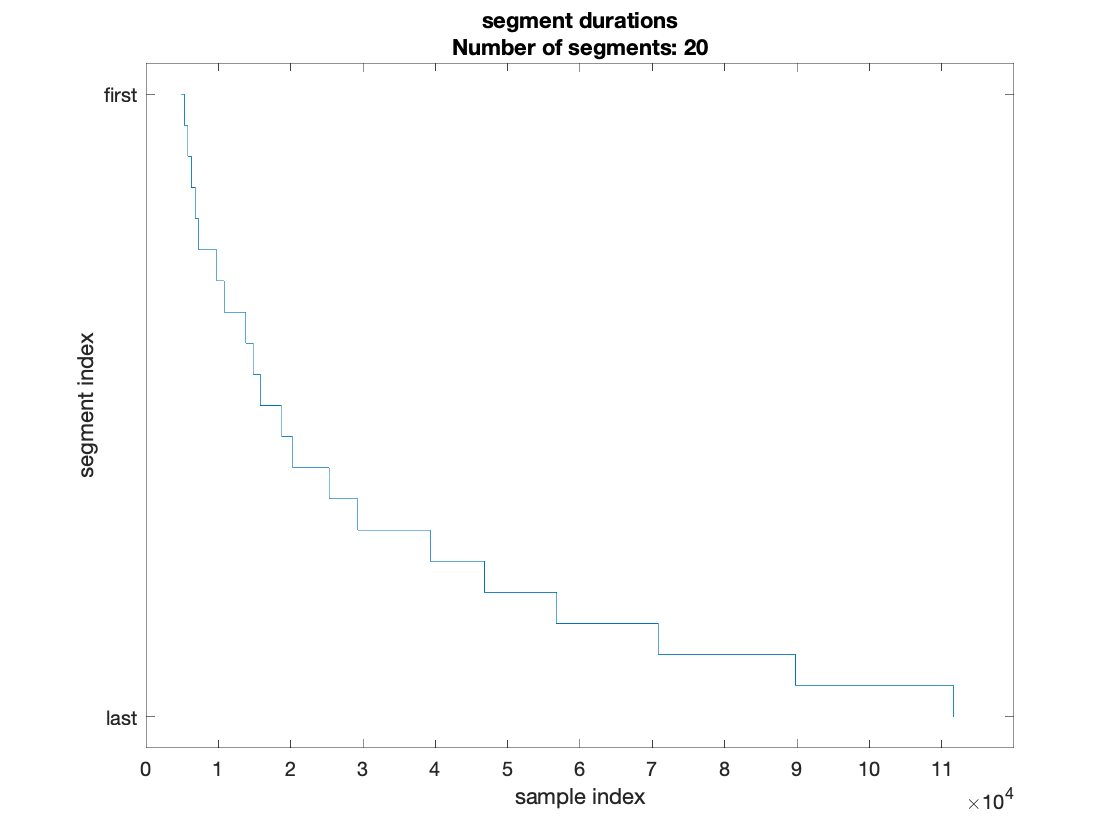

segBoundaries = [segStartIdxs length(X)]; % add the endpoint in for plotting
nBoundaries = length(segBoundaries);
stairs(segBoundaries, nBoundaries:-1:1);
yticks([1 nBoundaries])
xticks(round(segStartIdxs(1), -4):10000:round(length(X),-4))
yticklabels(["last" "first"]);
ylabel('segment index')
xlabel('sample index')
ylim([0,nBoundaries+1])
title({"Segment Boundaries", ...
    sprintf("Number of segments: %d", length(segStartIdxs))})


clear nBoundaries segBoundaries

### Calculate rolloff of velvet noise

velvetLPCorder = 60;
velvetRolloff = -10;
velvetFrqs = 10:70:500;
nVelvets = length(velvetFrqs);
velvetDur = floor(1.5 * Fs);
velvetMtx = zeros(velvetDur, nVelvets);
analysisResolution = 4096;

for i = 1:nVelvets
    velvetMtx(:, i) = velvet(velvetDur, velvetFrqs(i), Fs);
end

lpcOrder = 10;           % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(velvetMtx, velvetLPCorder, analysisResolution, Fs);

[rollidxs, rollfreqs, rollvals] = rolloffIdx(mags_norm, velvetRolloff, 50, Fs)

rollidxs =            8        2292        1592        1838        1007        2424        2323         551


rollfreqs = 	1.0e+04 *

         0    1.3383    0.9281    1.0723    0.5854    1.4156    1.3564    0.3182


rollvals =      0     0     0     0     0     0     0     0


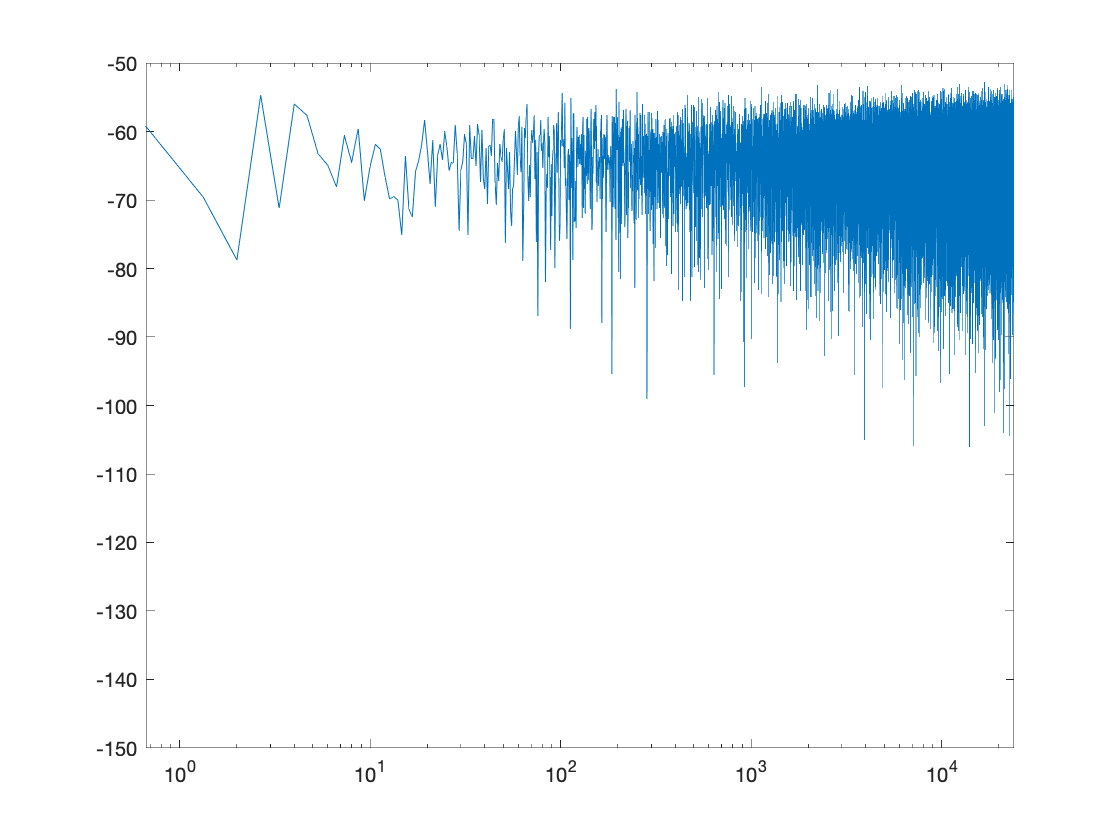

plotOneFFT(velvetMtx(:,end), size(velvetMtx, 1), Fs)

% clear X starttime endtime wintime hoptime rangetime nWin nWinSamps st i

starttime = 0.1;         % start time (seconds)
wintime = 2048/Fs;       % window duration (seconds)
frq_resolution = 4096;   % freqz resolution of LPC filter (number of points to generate)
% slide analysis window until the -20 cutoff frequency crosses the 
% specified frequency
hop = 1;       % window hop size to slide on each iteration (fraction of wintime)
maxSlide = 0.5;   % bail if the window slides this far without getting result

winSamps = floor(wintime * Fs);
hopSamp = floor(hop * winSamps);
winStart = floor(starttime * Fs);
maxSlideSamp = floor(maxSlide * Fs);

segStartSamps = [winStart]; % store the location of the first segment

maxCnt = ceil(maxSlideSamp/hopSamp);

cutoffFreq = 20000;
thisrms = 20;
for i = 2:length(rollofffreqs)
    rollFrq = rollofffreqs(i);
    rollRms = rolloffrms(i);
    cnt = 0;
%      && (cnt < maxCnt)
    while (cutoffFreq > rollFrq) || (thisrms > rollRms)
    
        % advance the window
        winStart = winStart + hopSamp;
        
        % retrieve samples
        segment = getSamples(X, winStart, winSamps);
        
        % calculate LPC spectrum estimate, convert to magnitudes dB
        [lpc_coefs, residual] = lpc(segment, lpcOrder);
        [H, w] = freqz(1, lpc_coefs, frq_resolution);
        spectrum = mag2db(abs(H));
        % normalize to channel peak
        specNorm = db2mag(spectrum);
        specNorm = specNorm ./ max(specNorm); 
        specNorm = mag2db(specNorm);
        
        clear spectrum;
        
        % calculate the -20dB cutoff freq
        srchSpec = specNorm(minFrqIdx:end);
        [d, ix] = min(abs(srchSpec - rolloff));
        ix = ix + minFrqIdx-1; % restore index
        cutoffFreq = w(ix)/pi * (Fs/2);
        
        thisrms = rms(segment); % calc rms
 
        cnt = cnt+1;
    end
    if cnt <= maxCnt
        segStartSamps = [segStartSamps winStart];
        fprintf("got out in %d iters at %dHz %f rms (%d/%f)", cnt, round(cutoffFreq), thisrms, round(rollFrq), rollRms);
    else
        warning("Exceeded rolloff search range on window " + i)
    end
end

steps = segStartSamps(2:end) - segStartSamps(1:end-1);

plot(steps)

## Assign segment boundary to each frequency division

starttime = 0.1;         % start time (seconds)
wintime = 2048/Fs;       % window duration (seconds)
frq_resolution = 4096;   % freqz resolution of LPC filter (number of points to generate)
% slide analysis window until the -20 cutoff frequency crosses the 
% specified frequency
hop = 1;       % window hop size to slide on each iteration (fraction of wintime)
maxSlide = 0.5;   % bail if the window slides this far without getting result

winSamps = floor(wintime * Fs);
hopSamp = floor(hop * winSamps);
winStart = floor(starttime * Fs);
maxSlideSamp = floor(maxSlide * Fs);

segStartSamps = [winStart]; % store the location of the first segment

maxCnt = ceil(maxSlideSamp/hopSamp);

cutoffFreq = 20000;
thisrms = 20;
for i = 2:length(rollofffreqs)
    rollFrq = rollofffreqs(i);
    rollRms = rolloffrms(i);
    cnt = 0;
%      && (cnt < maxCnt)
    while (cutoffFreq > rollFrq) || (thisrms > rollRms)
    
        % advance the window
        winStart = winStart + hopSamp;
        
        % retrieve samples
        segment = getSamples(X, winStart, winSamps);
        
        % calculate LPC spectrum estimate, convert to magnitudes dB
        [lpc_coefs, residual] = lpc(segment, lpcOrder);
        [H, w] = freqz(1, lpc_coefs, frq_resolution);
        spectrum = mag2db(abs(H));
        % normalize to channel peak
        specNorm = db2mag(spectrum);
        specNorm = specNorm ./ max(specNorm); 
        specNorm = mag2db(specNorm);
        
        clear spectrum;
        
        % calculate the -20dB cutoff freq
        srchSpec = specNorm(minFrqIdx:end);
        [d, ix] = min(abs(srchSpec - rolloff));
        ix = ix + minFrqIdx-1; % restore index
        cutoffFreq = w(ix)/pi * (Fs/2);
        
        thisrms = rms(segment); % calc rms
 
        cnt = cnt+1;
    end
    if cnt <= maxCnt
        segStartSamps = [segStartSamps winStart];
        fprintf("got out in %d iters at %dHz %f rms (%d/%f)", cnt, round(cutoffFreq), thisrms, round(rollFrq), rollRms);
    else
        warning("Exceeded rolloff search range on window " + i)
    end
end

steps = segStartSamps(2:end) - segStartSamps(1:end-1);

plot(steps)

# Whiten the segments, measure their power

% "whiten" the original segments
white_segments = zeros(size(segments));
for i = 1:nSig
    white_segments(:,i) = filter(lpc_coefs(i, :), [1], segments(:,i));
end

% recompute spectrum estimate ... is it flat?
lpcOrder = 10;       % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

nSig = size(white_segments, 2);  % number of signals to analyze
white_specEnv = zeros(frq_resolution, nSig); % a matrix to hold all the segments' spectral envs

[whitened_lpc_coefs, residual] = lpc(white_segments, lpcOrder);

for i = 1:nSig
%     [lpc_coefs, residual] = lpc(seg{i}, lpcOrder);
%     [H, w] = freqz(1, lpc_coefs(i, :), resolution); % spectral estimate
    [H, w] = freqz(whitened_lpc_coefs(i, :), 1, frq_resolution); % whitening filt
    white_specEnv(:, i) = mag2db(abs(H));
end

% normalize to channel peak
% specNorm = db2mag(specEnv);
% specNorm = specNorm ./ max(specNorm); 
% specNorm = mag2db(specNorm);

## Plot whitened spectrum

f = w/pi * (Fs/2);
% plot(specEnv(:,1))
semilogx(f, specNorm)
% semilogx(f, white_specEnv) % plot LPC filter response
% plot(f, white_specEnv) % plot LPC filter response

nSig = size(white_specEnv, 2);

% Colors
hueStart = 0.3;
hueSpan = 0.1;
hue = linspace(hueStart,hueStart+hueSpan,nSig); % hue
sat = linspace(1, 1, nSig);     % saturation
val = linspace(0.2, 1, nSig);   % value
hsv = [hue' sat' val']; 
rgb = hsv2rgb(hsv);
colororder(rgb);

axis tight;
xlim([80 20000]);
% ylim([-100 0])
xticks(125*2.^(0:7))

### Plot RMS of each whitened segment

whiteRMS = rms(white_segments)
plot(mag2db(whiteRMS))

# Plot segmented FFT

Uses single or multi-segment fft function below

% plotOneFFT(seg{1}, Fs)
plotMultiFFT(segments, 512, Fs)

legend()

# :: functions :: PlotOneFFT, PlotMultiFFT 

- Note: **fftshift()** shifts bins to put 0Hz at the center (odd N) or center +1 (even N)

function [mags mags_norm freqs coeffs] = lpcData(signal, lpc_order, freq_resolution, Fs, whiten)
    % [mags freqs coeffs] = lpcData(signal, lpc_order, freq_resolution, whiten)
    % (((input)))
    %           signal : column-major input signal matrix
    %        lpc_order : order of LPC filter to generate
    %  freq_resolution : number of frequencies to evaluate the magnitude 
    %                    spectrum
    %               Fs : sample rate
    %           whiten : optional flag to perform freq analysis on the LPC
    %                    coefficients treated as a whitening filter
    % (((output)))
    %      mags : frequency magnitudes of the spectral estimate in dB
    % mags_norm : normalized frequency magnitudes of the spectral estimate in dB
    %     freqs : frequencies corresponding to the spectral magnitudes
    %    coeffs : the LPC coefficients
    
    % enforce column vector on 1-channel signal
    if size(signal, 1) == 1
        signal =  signal';
    end
    % handle whitening option
    whitenfilt = false; % default: analyse a whitening filter
    if nargin > 4
        if whiten > 0
            whitenfilt = true
        end
    end
    
    coeffs = lpc(signal, lpc_order)'; % note: column-major
    nchan = size(signal, 2);
    mags = zeros(freq_resolution, nchan);
    mags_norm = zeros(freq_resolution, nchan);
    freqs = zeros(freq_resolution, 1);
    % 
    for i = 1:nchan
        if whitenfilt
            [H, w] = freqz(coeffs(:, i), 1, freq_resolution);
        else
            [H, w] = freqz(1, coeffs(:,i), freq_resolution);
        end
        m = abs(H);
        mags_norm(:, i) = mag2db(m./max(m));
        mags(:, i) = mag2db(m);
    end
    freqs(:,1) = (w/pi) * (Fs/2);
end

function plotOneFFT(signal, N, Fs)
    zoom = [0 Fs/2];         % "zoom in" on this freq range
    H = fft(signal, N);
    mag = abs(H)*2/N;
    mag = fftshift(mag);
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N); % spectrum 0 -> Nyquist
    mag = mag(pidx);
    mag = mag2db(mag);
    f = linspace(0, Fs/2, length(mag));
    
%     stem(f, mag);
    semilogx(f, mag);
    xlim(zoom);              % zoom via plot limits
    ylim([-150 -50])
end

function plotMultiFFT(signalCell, N, Fs)
    % plotMultiFFT(signalCell, N, Fs)
    %    [input]
    % signalCell: a cell array containing signals to perform FFT
    %          N: FFT size
    %         Fs: sample rate of signal
    
    mags = zeros(N, length(signalCell)); % matrix to hold FFT analysis
    
    % "zoom in" on this freq range (via xlim)
    % Change this is you want a specific freq range
    zoom = [0 Fs/2];                     
    
    nSig = length(signalCell);
    for i=1:nSig
        mags(:,i) = fft(signalCell{i}, N);
    end
    mags = abs(mags)*2/N;
    mags = fftshift(mags);    
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N);        % spectrum 0 -> Nyquist
    mags = mags(pidx, :);
    mags = mags./max(max(mags));    % normalize spectra
    mags = mag2db(mags);
%     mags = mags./max(mags);
    
    f = linspace(0, Fs/2, length(mags)); % bin frequencies 
    semilogx(f, mags);
    xlim(zoom);
    ylim([-80 0]);
end

function Y = getSamples(X, st, N)
    % getSamples(X, st, N)
    %    [input]
    %  X: signal buffer
    % st: start sample of returned frames
    %  N: number of samples to return
    if st+(N-1) > length(X)
        warning('requested samples exceed the length of ht input buffer, clamping at the end');
        N = length(X) - st;
    end
    Y = X(st:st+N-1);
end

function Y = getSamplesDur(X, st, D, Fs)
    % getSamplesDur(X, st, N)
    %  INPUT
    %      X : signal buffer
    %     st : start time of returned frames
    %      D : duration of window to return
    %     Fs : sample rate of signal buffer
    stSamp = floor(Fs * st);
    durSamp = floor(Fs * D);
    Y = getSamples(X, stSamp, durSamp);
end

function rgb = genColors(hue_start, hue_span, num_cols)
    % genColors(hue_start, hue_span, num_plots)
    %      INPUT
    %  hue_start : hue start position {0,1}
    %   hue_span : hue range {0,1}
    %   num_cols : number of colors to generate
    hue = linspace(hue_start, hue_start+hue_span, num_cols); % hue
    sat = linspace(1, 1, num_cols);     % saturation
    val = linspace(0.2, 1, num_cols);   % value
    hsv = [hue' sat' val']; 
    rgb = hsv2rgb(hsv);
end

function [idxs, freqs, vals] = rolloffIdx(mags, rolloff, min_freq, Fs)
    % idxs = rolloffIdx(mags, rolloff, min_freq, Fs)
    %          INPUTS
    %            mags : column-major matrix of NORMALIZED spectral magnitudes
    %         rolloff : dB level to search for in rolloff countour
    %        min_freq : search above this frequency (shrink the search space)
    % freq_resolution : number of points comprising the full magnitude
    %                   spectrum
    %              Fs : sample rate
    %    OUTPUTS
    %       idxs : vector of indicies closest to the rolloff
    %      freqs : frequencies at idxs
    %       vals : values in mags matrix at indxs
    
    % narrow the search space: omit part of the spectrum below min_freq
    nFreqs = length(mags);
    minFrqIdx = floor(min_freq/(Fs/2) * nFreqs);
    srchSpec = mags(minFrqIdx:end, :);
    
    % find closest values, by index
    [d, ix] = min(abs(srchSpec - rolloff));
    % restore index from min_freq offset
    idxs = ix + minFrqIdx-1;    
    
%     cols = 1:size(mags, 2);
%     freqs = sub2ind(size(mags), idxs, cols);
%     freqs = w(ix)/pi * (Fs/2);
    freqs = Fs/2 / nFreqs * (ix-1);
    
    vals = mags(idxs); % cutoff values in each segment
end

% calculate the -20dB cutoff freq
%         srchSpec = specNorm(minFrqIdx:end);
%         [d, ix] = min(abs(srchSpec - rolloff));
%         ix = ix + minFrqIdx-1; % restore index
%         cutoffFreq = w(ix)/pi * (Fs/2);